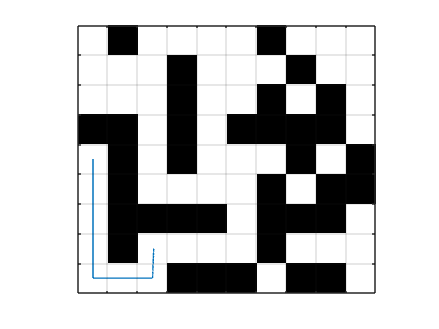

clear all
R = 0.05;
d1 = 0.25;
d2 = 0.3;

theta1 = 10;
theta2 = 10;
theta3 = 10;
theta4 = 10;
time = 8;
fi0 = 0;
x0 = 1;
y0 = 5;
simConfig.StopTime = int2str(time);
simulation = sim("model.slx", simConfig);
t = simulation.out(:,1);
xQ = simulation.out(:,2);
yQ = simulation.out(:,3);
fi = simulation.out(:,4);

theta1 = -10;
theta2 = 10;
theta3 = -10;
theta4 = 10;
time = 4;
fi0 = fi(end);
x0 = xQ(end);
y0 = yQ(end);
simConfig.StopTime = int2str(time);
simulation = sim("model.slx", simConfig);
t = [t;simulation.out(:,1)+(ones(length(simulation.out(:,1)),1)).*t(end)];
xQ = [xQ;simulation.out(:,2)];
yQ = [yQ;simulation.out(:,3)];
fi = [fi;simulation.out(:,4)];

theta1 = 5;
theta2 = -5;
theta3 = -5;
theta4 = 5;
time = 7;
fi0 = fi(end);
x0 = xQ(end);
y0 = yQ(end);
simConfig.StopTime = int2str(time);
simulation = sim("model.slx", simConfig);
t = [t;simulation.out(:,1)+(ones(length(simulation.out(:,1)),1)).*t(end)];
xQ = [xQ;simulation.out(:,2)];
yQ = [yQ;simulation.out(:,3)];
fi = [fi;simulation.out(:,4)];

theta1 = 10;
theta2 = 10;
theta3 = 10;
theta4 = 10;
time = 2;
fi0 = fi(end);
x0 = xQ(end);
y0 = yQ(end);
simConfig.StopTime = int2str(time);
simulation = sim("model.slx", simConfig);
t = [t;simulation.out(:,1)+(ones(length(simulation.out(:,1)),1)).*t(end)];
xQ = [xQ;simulation.out(:,2)];
yQ = [yQ;simulation.out(:,3)];
fi = [fi;simulation.out(:,4)];

ROW = 9;
COL = 10;

gridd = [
    1, 0, 1, 1, 1, 1, 0, 1, 1, 1;
    1, 1, 1, 0, 1, 1, 1, 0, 1, 1;
    1, 1, 1, 0, 1, 1, 0, 1, 0, 1;
    0, 0, 1, 0, 1, 0, 0, 0, 0, 1;
    1, 0, 1, 0, 1, 1, 1, 0, 1, 0;
    1, 0, 1, 1, 1, 1, 0, 1, 0, 0;
    1, 0, 0, 0, 0, 1, 0, 0, 0, 1;
    1, 0, 1, 1, 1, 1, 0, 1, 1, 1;
    1, 1, 1, 0, 0, 0, 1, 0, 0, 1
];
imagesc(gridd);
colormap(gray);
axis equal;xlim([0.5 COL+0.5])
ylim([0.5 ROW+0.5])
xticks(0.5:1:10.5)
yticks(0.5:1:10.5)
xticklabels('')
yticklabels('')
grid on;
hold on
plot(xQ, yQ)
hold off

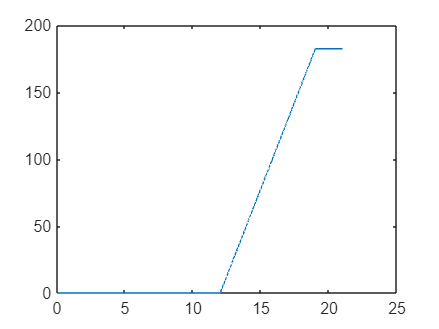

figure
plot(t,fi.*(180/pi))